## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 65);

% Specify sheet and range
opts.Sheet = "Supplementary material_final";
opts.DataRange = "A3:BM132";

% Specify column names and types
opts.VariableNames = ["VarName1", "Ageyears", "Gender", "Var4", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "UPDRSIIITotal", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.SelectedVariableNames = ["VarName1", "Ageyears", "Gender", "AgeOfDiseaseOnsetyears", "DurationOfDiseaseFromFirstSymptomsyears", "UPDRSIIITotal", "EST_R", "RST_R", "AST_R", "DPI_R", "DVI_R", "GVI_R", "DUS_R", "DUF_R", "RLR_R", "PIR_R", "RSR_R", "LRE_R", "EST_M", "RST_M", "AST_M", "DPI_M", "DVI_M", "GVI_M", "DUS_M", "DUF_M", "RLR_M", "PIR_M", "RSR_M", "LRE_M"];
opts.VariableTypes = ["string", "double", "categorical", "char", "double", "double", "char", "char", "char", "char", "char", "char", "char", "double", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "char", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify variable properties
opts = setvaropts(opts, ["VarName1", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["VarName1", "Gender", "Var4", "Var7", "Var8", "Var9", "Var10", "Var11", "Var12", "Var13", "Var15", "Var16", "Var17", "Var18", "Var19", "Var20", "Var21", "Var22", "Var23", "Var24", "Var25", "Var26", "Var27", "Var28", "Var29", "Var30", "Var31", "Var32", "Var33", "Var34", "Var35", "Var36", "Var37", "Var38", "Var39", "Var40", "Var41"], "EmptyFieldRule", "auto");

% Import the data
data = readtable("data.xls", opts, "UseExcel", false);
clear opts


groups(1:30,1) = categorical("PD");
groups(31:80,1) = categorical("RBD");
groups(81:130,1) = categorical("HC");
gender = data.Gender;

data(:,7:end) = filloutliers(data(:,7:end),nan);



## Normality testing

normality = ["Group" data.Properties.VariableNames(7:end)];
normality = cellstr(normality);
normality{2,1} = "PD";
normality{3,1} = "RBD";
normality{4,1} = "HC";


for i = 1:24
    x = data(:,i+6);
    x1 = x{1:30,:};
    x2 = x{31:80,:};
    x3 = x{81:130,:};
    [~,normality{2,i+1},~] = swtest(x1,0.05);
    [~,normality{3,i+1},~] = swtest(x2,0.05);
    [~,normality{4,i+1},~] = swtest(x3,0.05);

end
normality

normality = 4×25 cell array
    {'Group'}    {'EST_R' }    {'RST_R' }    {'AST_R' }    {'DPI_R' }    {'DVI_R' }    {'GVI_R' }    {'DUS_R' }    {'DUF_R' }    {'RLR_R' }    {'PIR_R' }    {'RSR_R' }    {'LRE_R' }    {'EST_M' }    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M' }    {'GVI_M' }    {'DUS_M' }    {'DUF_M' }    {'RLR_M' }    {'PIR_M' }    {'RSR_M' }    {'LRE_M' }
    {["PD" ]}    {[0.3433]}    {[0.4042]}    {[0.5345]}    {[0.4206]}    {[0.0417]}    {[0.7567]}    {[0.0764]}    {[0.3000]}    {[0.2062]}    {[0.4378]}    {[0.3079]}    {[0.0643]}    {[0.2262]}    {[0.2951]}    {[0.7984]}    {[0.2546]}    {[0.1019]}    {[0.3800]}    {[0.0334]}    {[0.2829]}    {[0.4513]}    {[0.0293]}    {[0.7829]}    {[0.8217]}
    {["RBD"]}    {[0.0419]}    {[0.2612]}    {[0.0429]}    {[0.0220]}    {[0.7959]}    {[0.9489]}    {[0.0048]}    {[0.5894]}    {[0.4578]}    {[0.8119]}    {[0.7356]}    {[0.1203]}    {[0.2151]}    {[0.0834]}    {[0.8285]}    {[0.0948]}    {[0.1563]}    {[0.5004]}    {[0

Zahodit: DUS, PIR

## Homogenity testing

homogenity = [data.Properties.VariableNames(7:end)];
homogenity = cellstr(homogenity);
for i = 1:24
    x = data{:,i+6};
    
    homogenity{2,i} = vartestn(x,groups,"Display","off");

end
homogenity

homogenity = 2×24 cell array
    {'EST_R' }    {'RST_R' }    {'AST_R' }    {'DPI_R' }    {'DVI_R' }    {'GVI_R' }    {'DUS_R' }    {'DUF_R' }    {'RLR_R' }    {'PIR_R' }    {'RSR_R' }    {'LRE_R' }    {'EST_M' }    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M' }    {'GVI_M' }    {'DUS_M' }    {'DUF_M' }    {'RLR_M' }    {'PIR_M' }    {'RSR_M' }    {'LRE_M' }
    {[0.1210]}    {[0.9357]}    {[0.2084]}    {[0.0773]}    {[0.0536]}    {[0.6309]}    {[0.6413]}    {[0.9498]}    {[0.2920]}    {[0.6798]}    {[0.2428]}    {[0.9034]}    {[0.1226]}    {[0.7066]}    {[0.0633]}    {[0.0238]}    {[0.3448]}    {[0.7944]}    {[0.5677]}    {[0.3442]}    {[0.2245]}    {[0.8823]}    {[0.8833]}    {[0.5473]}


Zahodit: -

## UDPRS III t-test

normality = ["Group" "p-values"];
normality(2,1) = "PD";
normality(3,1) = "RBD";
[~,normality(2,2),~] = swtest(data.UPDRSIIITotal(1:30),0.05);
[~,normality(3,2),~] = swtest(data.UPDRSIIITotal(31:80),0.05);
normality

normality = 3×2 string array
    "Group"    "p-values"  
    "PD"       "0.01884"   
    "RBD"      "0.00061835"



homogenity = ["p-value"];
homogenity(2,1) = vartestn(data.UPDRSIIITotal(1:80),groups(1:80),"Display","off");
homogenity

homogenity = 2×1 string array
    "p-value"
    "5.1267e-11"



[h,p,~,stats] = ttest2(data.UPDRSIIITotal(1:30),data.UPDRSIIITotal(31:80))

h = 1

p = 1.2351e-11

stats = struct with fields:
    tstat: 7.9390
       df: 78
       sd: 8.2214


H0: Není rozdíl mezi UPDRSIII u PD a RBD skupiny.

H1 :Je rozdíl mezi UPDRSIII u PD a RBD skupiny.

Zamítáme H0: t(78) = 7.94, p < 0.001

U RBD je zhoršení motoriky mnohem menší než u PD

## ANOVA

anova_pvals_mon = [];
anova_pvals_red = [];
for i = 1:12
    [anova_pvals_mon(2:4,i),~,anova_stats_mon(i).stats] = anovan(data{:,i+18},{groups, gender},'varnames',{'group','gender'},'model','interaction','display','off');
end
for i = 1:12
    [anova_pvals_red(2:4,i),~,anova_stats_red(i).stats] = anovan(data{:,i+6},{groups, gender},'varnames',{'group','gender'},'model','interaction','display','off');
end



anova_pvals_mon(:,[1 5 7 8 9 10 11 12]) = nan;
anova_pvals_mon = num2cell(anova_pvals_mon);
anova_pvals_mon(1,:) = [data.Properties.VariableNames(19:end)];
anova_pvals_mon

anova_pvals_mon = 4×12 cell array
    {'EST_M'}    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M'}    {'GVI_M'     }    {'DUS_M'}    {'DUF_M'}    {'RLR_M'}    {'PIR_M'}    {'RSR_M'}    {'LRE_M'}
    {[  NaN]}    {[0.0052]}    {[0.8514]}    {[0.0046]}    {[  NaN]}    {[    0.7997]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}
    {[  NaN]}    {[0.0049]}    {[0.6198]}    {[0.0034]}    {[  NaN]}    {[2.7169e-04]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}
    {[  NaN]}    {[0.7759]}    {[0.0250]}    {[0.9179]}    {[  NaN]}    {[    0.7885]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}


anova_pvals_red(:,[1 3 4 5 6 7 8 9 10 12]) = nan;
anova_pvals_red = num2cell(anova_pvals_red);
anova_pvals_red(1,:) = [data.Properties.VariableNames(7:18)];
anova_pvals_red

anova_pvals_red = 4×12 cell array
    {'EST_R'}    {'RST_R'     }    {'AST_R'}    {'DPI_R'}    {'DVI_R'}    {'GVI_R'}    {'DUS_R'}    {'DUF_R'}    {'RLR_R'}    {'PIR_R'}    {'RSR_R' }    {'LRE_R'}
    {[  NaN]}    {[    0.0952]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[0.8934]}    {[  NaN]}
    {[  NaN]}    {[1.9269e-04]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[0.9612]}    {[  NaN]}
    {[  NaN]}    {[    0.2195]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[0.5329]}    {[  NaN]}


#### Závěr: pohlaví zkresluje výsledek -> separace podle pohlaví

## Gender separation

female_ind = gender == 'F';
male_ind = ~female_ind;

data_female = data(female_ind,:);
data_male = data(male_ind,:);

groups_female = groups(female_ind);
groups_male = groups(male_ind);

## Females

anova_pvals_mon = [];
anova_pvals_red = [];

for i = 1:12
    [anova_pvals_mon(2,i),~,anova_stats_mon(i).stats] = anova1(data_female{:,i+18}, groups_female,"off");
end
for i = 1:12
    [anova_pvals_red(2,i),~,anova_stats_red(i).stats] = anova1(data_female{:,i+6}, groups_female,"off");
end



anova_pvals_mon(:,[1 5 7 8 9 10 11 12]) = nan;
anova_pvals_mon = num2cell(anova_pvals_mon);
anova_pvals_mon(1,:) = [data.Properties.VariableNames(19:end)];
anova_pvals_mon

anova_pvals_mon = 2×12 cell array
    {'EST_M'}    {'RST_M' }    {'AST_M' }    {'DPI_M' }    {'DVI_M'}    {'GVI_M' }    {'DUS_M'}    {'DUF_M'}    {'RLR_M'}    {'PIR_M'}    {'RSR_M'}    {'LRE_M'}
    {[  NaN]}    {[0.1069]}    {[0.1649]}    {[0.1446]}    {[  NaN]}    {[0.9811]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}



anova_pvals_red(:,[1 3 4 5 6 7 8 9 10 12]) = nan;
anova_pvals_red = num2cell(anova_pvals_red);
anova_pvals_red(1,:) = [data.Properties.VariableNames(7:18)];
anova_pvals_red

anova_pvals_red = 2×12 cell array
    {'EST_R'}    {'RST_R' }    {'AST_R'}    {'DPI_R'}    {'DVI_R'}    {'GVI_R'}    {'DUS_R'}    {'DUF_R'}    {'RLR_R'}    {'PIR_R'}    {'RSR_R' }    {'LRE_R'}
    {[  NaN]}    {[0.8947]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[0.5684]}    {[  NaN]}


### Závěr: u žen nejsou skupiny rozlišitelné, možná nízkým počtem vzorků (jen 9 na každou skupinu)

## Males

anova_pvals_mon = [];
anova_pvals_red = [];

for i = 1:12
    [anova_pvals_mon(2,i),~,anova_stats_mon(i).stats] = anova1(data_male{:,i+18}, groups_male,"off");
end
for i = 1:12
    [anova_pvals_red(2,i),~,anova_stats_red(i).stats] = anova1(data_male{:,i+6}, groups_male,"off");
end

anova_pvals_mon(:,[1 5 7 8 9 10 11 12]) = nan;
anova_pvals_mon = num2cell(anova_pvals_mon);
anova_pvals_mon(1,:) = [data.Properties.VariableNames(19:end)];
anova_pvals_mon

anova_pvals_mon = 2×12 cell array
    {'EST_M'}    {'RST_M'     }    {'AST_M' }    {'DPI_M'     }    {'DVI_M'}    {'GVI_M' }    {'DUS_M'}    {'DUF_M'}    {'RLR_M'}    {'PIR_M'}    {'RSR_M'}    {'LRE_M'}
    {[  NaN]}    {[6.9871e-04]}    {[0.0781]}    {[9.3158e-04]}    {[  NaN]}    {[0.3648]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}



anova_pvals_red(:,[1 3 4 5 6 7 8 9 10 12]) = nan;
anova_pvals_red = num2cell(anova_pvals_red);
anova_pvals_red(1,:) = [data.Properties.VariableNames(7:18)];
anova_pvals_red

anova_pvals_red = 2×12 cell array
    {'EST_R'}    {'RST_R'     }    {'AST_R'}    {'DPI_R'}    {'DVI_R'}    {'GVI_R'}    {'DUS_R'}    {'DUF_R'}    {'RLR_R'}    {'PIR_R'}    {'RSR_R' }    {'LRE_R'}
    {[  NaN]}    {[5.7592e-04]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[  NaN]}    {[0.5526]}    {[  NaN]}


## Post-hoc

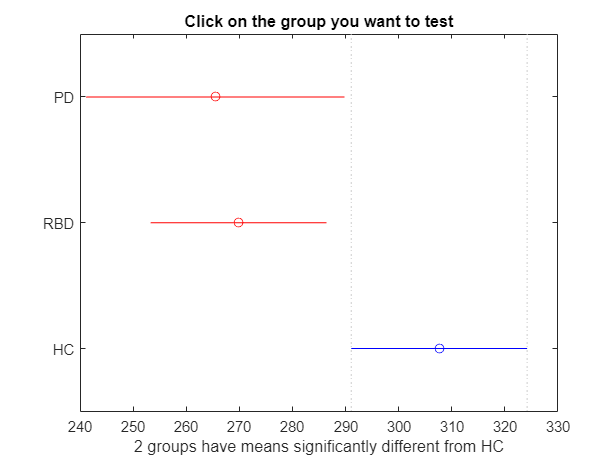

[c,m,h,gnames] = multcompare(anova_stats_mon(2).stats,"Alpha",0.00833,"CriticalValueType","tukey-kramer");

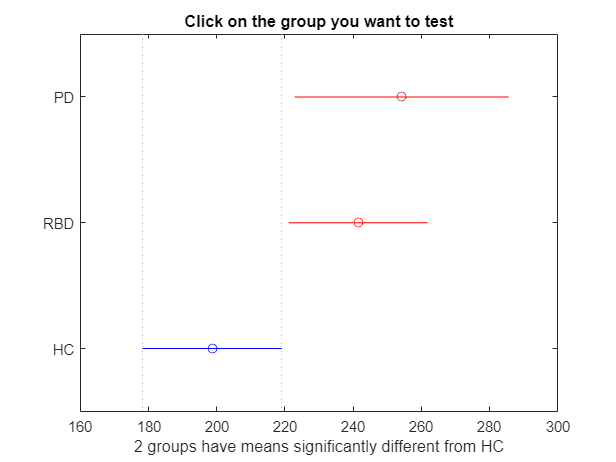

[c,m,h,gnames] = multcompare(anova_stats_mon(4).stats,"Alpha",0.00833,"CriticalValueType","tukey-kramer");

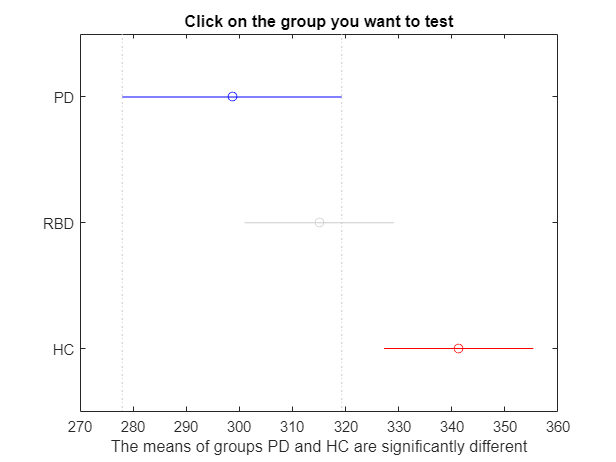

[c,m,h,gnames] = multcompare(anova_stats_red(2).stats,"Alpha",0.00833,"CriticalValueType","tukey-kramer");